## Combined Exp

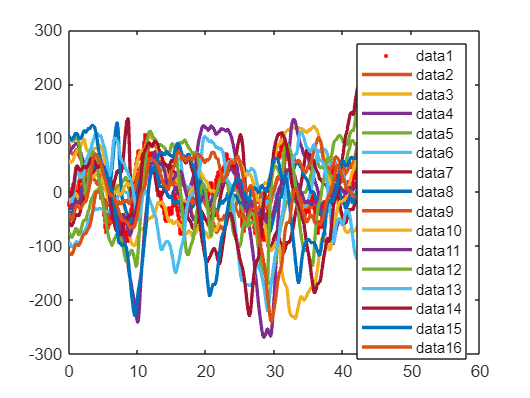

experiments = {
    % 'samsun low light window 7cm\7cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_04_22_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_08_20_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_10_11_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_11_50_2022_TRACK.xlsx',
    % 'samsun low light window 7cm\7cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LS_CL_Fri_Sep_16_10_13_41_2022_TRACK.xlsx',
    
    'Data\samsun low light window 21cm\21cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_46_43_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_48_50_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_50_57_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_54_12_2022_TRACK.xlsx',
    'Data\samsun low light window 21cm\21cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LL_CL_Thu_Sep_15_09_56_25_2022_TRACK.xlsx',
    
    'Data\samsun low light window 14cm\14cm\trial01_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_54_05_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial02_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_13_56_51_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial03_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_00_01_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial04_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_02_22_2022_TRACK.xlsx',
    'Data\samsun low light window 14cm\14cm\trial05_DR_sos_eigenmania_fish01_IL_WY_LM_CL_Thu_Sep_15_14_04_12_2022_TRACK.xlsx',
   
    'Data\samsun low light nowindow 21cm\21cm\trial01_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_03_18_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial03_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_07_26_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial04_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_09_31_2022_TRACK.xlsx',
    'Data\samsun low light nowindow 21cm\21cm\trial05_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_11_33_2022_TRACK.xlsx',
    };

% readtable("samsun low light nowindow 21cm\21cm\trial02_DL_sos_eigenmania_fish01_IL_WN_LL_CL_Thu_Sep_15_12_05_25_2022_TRACK.xlsx")

fishes = [];

for experimentIdx = 1:length(experiments)
    experiment = experiments{experimentIdx};
    table = readtable(experiment);
    fish = table.Fish;
    fish = fish(76:end);
    fishes = [fishes detrend(fish)];
end

table_0 = readtable(experiments{1});
cage = table_0.Cage;
cage = cage(76:end);
cage = detrend(cage);

Fs = 25;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(cage);             % Length of signal
t = (0:L-1)*T;        % Time vector
f = Fs/L*(0:L-1);

figure,
hold on; box on;
plot(t, cage, '.r', 'LineWidth', 4);

for fish = fishes
    Fs = 25;
    t = 0:1/Fs:(length(fish)-1)/Fs;

    plot(t, fish, 'LineWidth', 2);
end

legend()

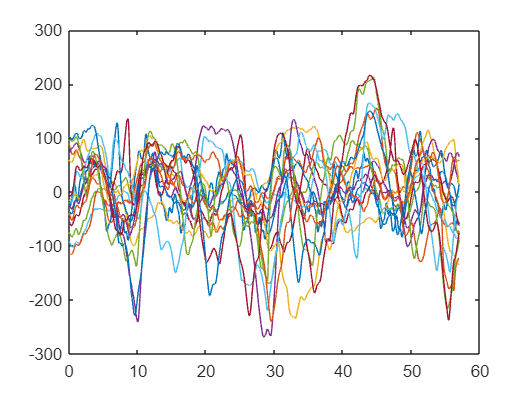

y = fishes;
u = cage;
num_outputs = length(y(1,:));

% Create an iddata object with your data
data = iddata(y, u, t(2) - t(1), 'ExperimentName', experiments);

figure, hold on, box on,
plot(t, u, t, y);

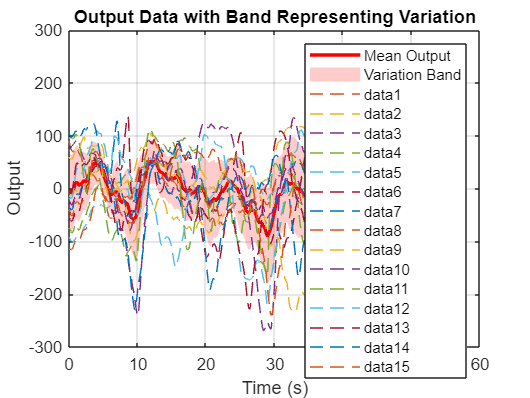

% Calculate the mean and standard deviation at each time point
y_mean = mean(y, 2);
y_std = std(y, 0, 2);

% Define the upper and lower bounds for the band
y_upper = y_mean + y_std;
y_lower = y_mean - y_std;

% Plot the mean output
figure;
plot(t, y_mean, 'r', 'LineWidth', 2);
hold on;

% Plot the band
fill([t'; flipud(t')], [y_upper; flipud(y_lower)], 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% Add labels and title
xlabel('Time (s)');
ylabel('Output');
title('Output Data with Band Representing Variation');
legend('Mean Output', 'Variation Band');
grid on;

% Optional: Plot individual output data
for i = 1:num_outputs
    plot(t, y(:, i), '--');
end

% Number of models to fit
num_models = 3;

% Initialize cell array for storing models
G_ests = cell(num_models, num_outputs);

% Define the transfer function structure for the model
K_initial = 1; % Initial guess for K
a_initial = 1; % Initial guess for a
tau_initial = 0.5; % Initial guess for tau
A_initial = 1;
w0_initial = 1;
etha_initial = 0.5;

% Loop through each output to estimate the model
for i = 1:num_outputs
    % Create idtf model with initial parameter values
    G0 = idtf(K_initial, [1 a_initial]);
    G1 = idtf(K_initial, [1 a_initial], 'InputDelay', tau_initial);
    G2 = idtf(A_initial*w0_initial^2, [1 2*etha_initial*w0_initial w0_initial^2], 'InputDelay', tau_initial);

    % Estimate the model parameters for each output
    G_ests{1, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G0);
    G_ests{2, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G1);
    G_ests{3, i} = pem(iddata(y(:, i), u, t(2) - t(1)), G2);
end

% Display the estimated 
% models
for i = 1:num_outputs
    for j = 1:num_models
        G_ests{j, i}
    end
end

ans =
  From input "u1" to output "y1":
   0.8199
  --------
  s + 1.57
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                 
Estimated using PEM on time domain data.
Fit to estimation data: 19.39%          
FPE: 1098, MSE: 1093                    
 
Model Properties

ans =
  From input "u1" to output "y1":
                  1.758
  exp(-0.5*s) * ---------
                s + 4.065
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients

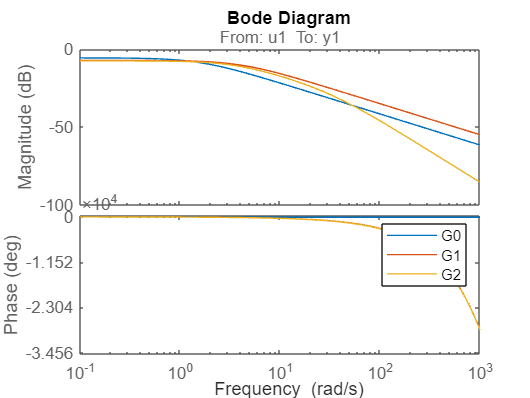

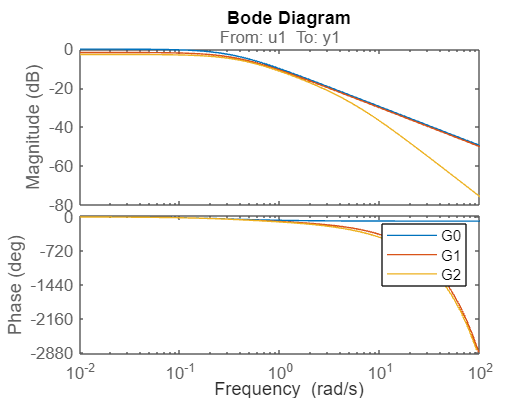

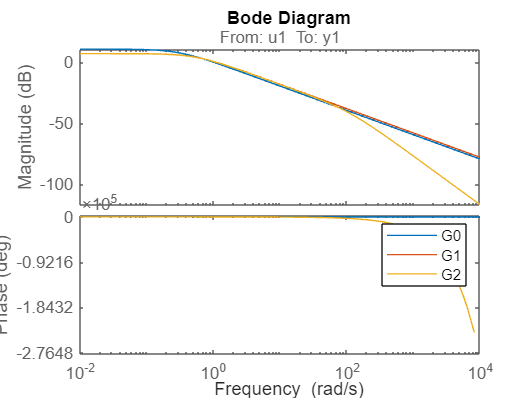

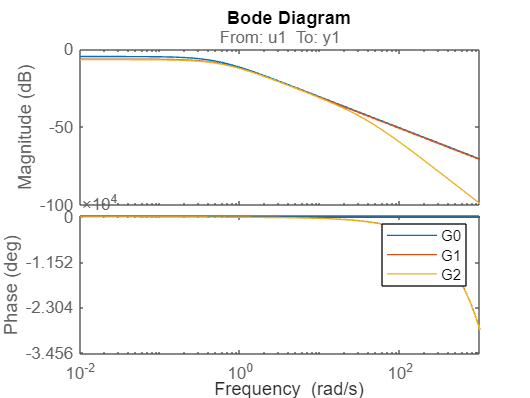

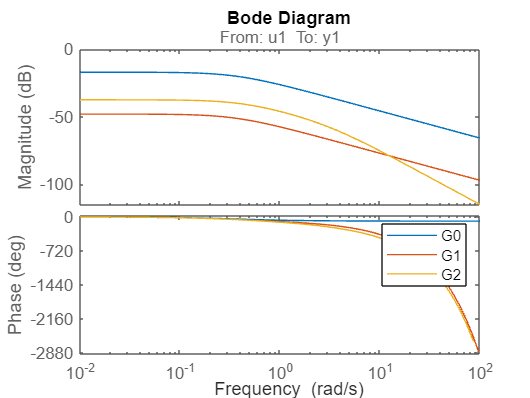

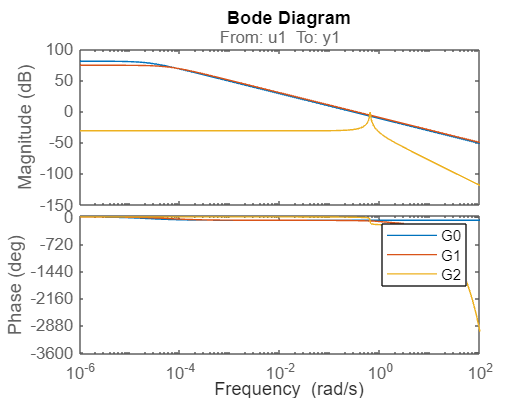

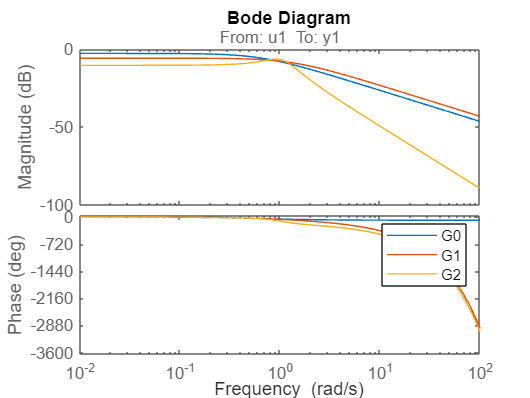

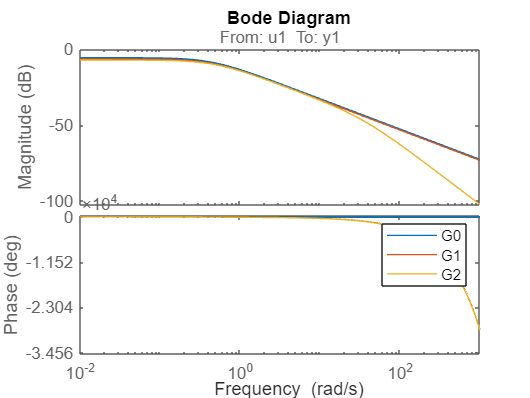

for i = 1:num_outputs
    figure, hold on, box on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        % showConfidence(h,3)
    end
    legend('G0', 'G1', 'G2');
end

% Initialize cell array for storing sim outputs
% y_sims = zeros(size(y));
y_sims = cell(num_models, num_outputs);

% Simulate the model output
for i = 1:num_outputs
    for j = 1:num_models
        y_sims{j, i} = lsim(G_ests{j, i}, u, t);
    end
end

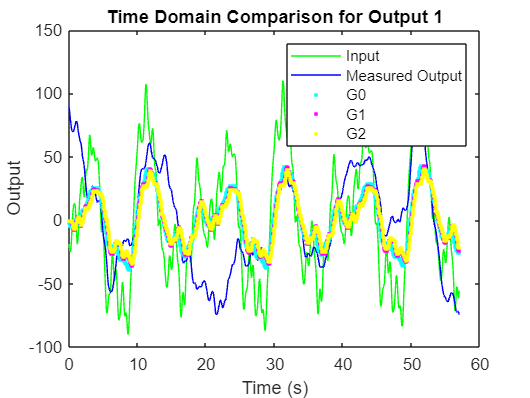

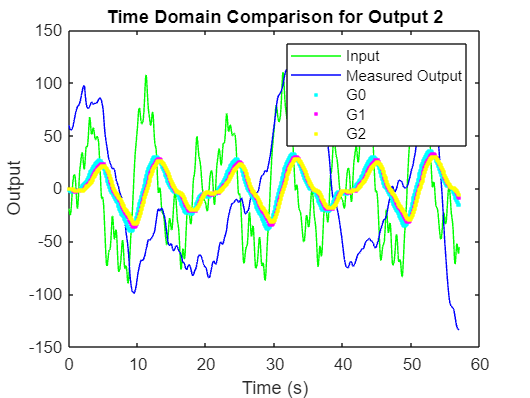

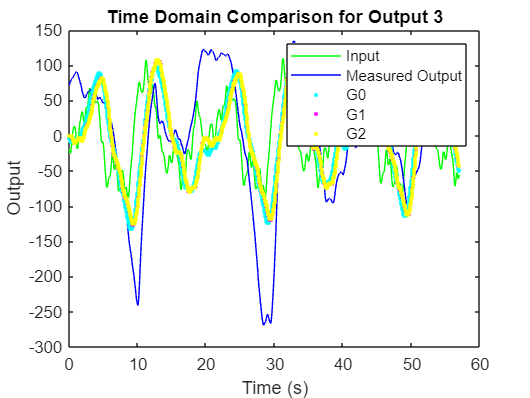

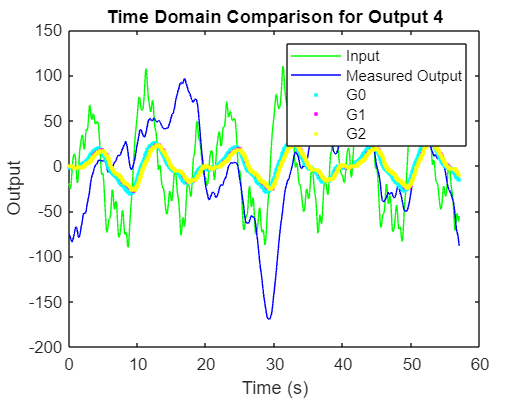

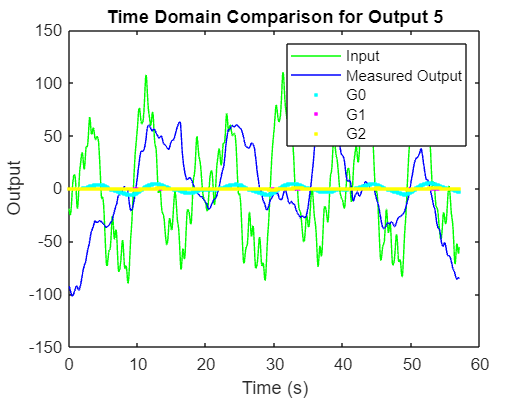

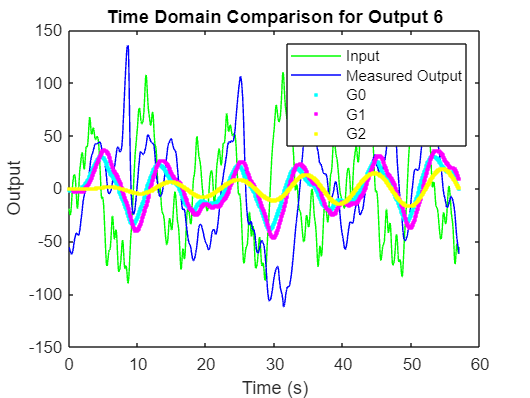

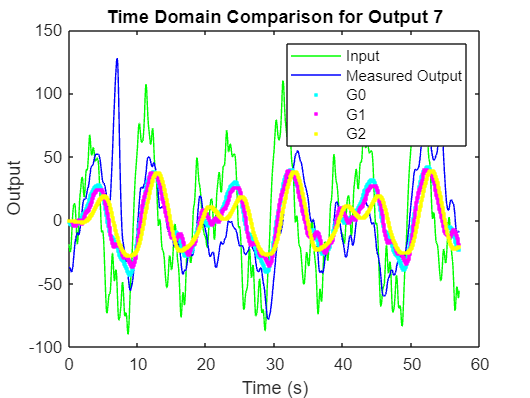

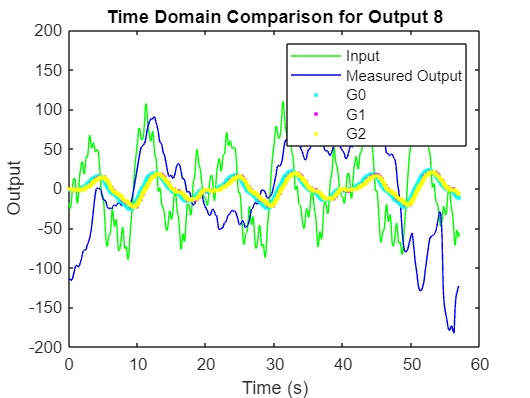

data_fft =

IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s), and the spectra for disturbances at the outputs.
Response data and disturbance spectra are available at 128 frequency points, ranging from 0.6136 rad/s to 78.54 rad/s.
 
Sample time: 0.04 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                 
Estimated using SPA on time domain data.
 
Model Properties


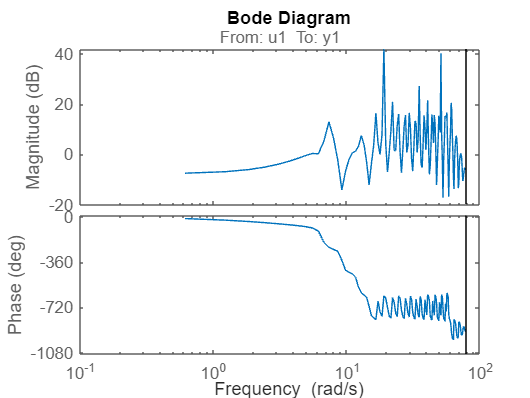

mag_estimated = mag_estimated(:,:,1) =

    0.4191


mag_estimated(:,:,2) =

    0.4190


mag_estimated(:,:,3) =

    0.4190


mag_estimated(:,:,4) =

    0.4188


mag_estimated(:,:,5) =

    0.4187


mag_estimated(:,:,6) =

    0.4185


mag_estimated(:,:,7) =

    0.4182


mag_estimated(:,:,8) =

    0.4179


mag_estimated(:,:,9) =

    0.4174


mag_estimated(:,:,10) =

    0.4167


mag_estimated(:,:,11) =

    0.4158


mag_estimated(:,:,12) =

    0.4145


mag_estimated(:,:,13) =

    0.4128


mag_estimated(:,:,14) =

    0.4105


mag_estimated(:,:,15) =

    0.4075


mag_estimated(:,:,16) =

    0.4035


mag_estimated(:,:,17) =

    0.4034


mag_estimated(:,:,18) =

    0.3981


mag_estimated(:,:,19) =

    0.3911


mag_estimated(:,:,20) =

    0.3822


mag_estimated(:,:,21) =

    0.3709


mag_estimated(:,:,22) =

    0.3570


mag_estimated(:,:,23) =

    0.3403


mag_estimated(:,:,24) =

    0.3208


mag_estimated(:,:,25) =

    0.2988


mag_estimated(:,:,26) =

    0.2748


mag_e

phase_estimated = phase_estimated(:,:,1) =

   -4.6357


phase_estimated(:,:,2) =

   -5.2696


phase_estimated(:,:,3) =

   -6.1556


phase_estimated(:,:,4) =

   -7.1905


phase_estimated(:,:,5) =

   -8.3991


phase_estimated(:,:,6) =

   -9.8107


phase_estimated(:,:,7) =

  -11.4591


phase_estimated(:,:,8) =

  -13.3836


phase_estimated(:,:,9) =

  -15.6303


phase_estimated(:,:,10) =

  -18.2523


phase_estimated(:,:,11) =

  -21.3112


phase_estimated(:,:,12) =

  -24.8784


phase_estimated(:,:,13) =

  -29.0355


phase_estimated(:,:,14) =

  -33.8761


phase_estimated(:,:,15) =

  -39.5066


phase_estimated(:,:,16) =

  -45.9578


phase_estimated(:,:,17) =

  -46.0463


phase_estimated(:,:,18) =

  -53.6284


phase_estimated(:,:,19) =

  -62.3985


phase_estimated(:,:,20) =

  -72.5143


phase_estimated(:,:,21) =

  -84.1436


phase_estimated(:,:,22) =

  -97.4630


phase_estimated(:,:,23) =

 -112.6591


phase_estimated(:,:,24) =

 -129.9318


phase_estimated(:,:,25) =

 -14

wout = 1.0e+03 *

    0.0001
    0.0001
    0.0001
    0.0002
    0.0002
    0.0002
    0.0002
    0.0003
    0.0003
    0.0004


mag_measured = mag_measured(:,:,1) =

   NaN


mag_measured(:,:,2) =

   NaN


mag_measured(:,:,3) =

   NaN


mag_measured(:,:,4) =

   NaN


mag_measured(:,:,5) =

   NaN


mag_measured(:,:,6) =

   NaN


mag_measured(:,:,7) =

   NaN


mag_measured(:,:,8) =

   NaN


mag_measured(:,:,9) =

   NaN


mag_measured(:,:,10) =

   NaN


mag_measured(:,:,11) =

   NaN


mag_measured(:,:,12) =

   NaN


mag_measured(:,:,13) =

    0.4212


mag_measured(:,:,14) =

    0.4276


mag_measured(:,:,15) =

    0.4340


mag_measured(:,:,16) =

    0.4405


mag_measured(:,:,17) =

    0.4406


mag_measured(:,:,18) =

    0.4473


mag_measured(:,:,19) =

    0.4613


mag_measured(:,:,20) =

    0.4791


mag_measured(:,:,21) =

    0.4986


mag_measured(:,:,22) =

    0.5314


mag_measured(:,:,23) =

    0.5697


mag_measured(:,:,24) =

    0.6229


mag_measured(:,:,25) =

    0.6942


mag_measured(:,:,26) =

    0.7878


mag_measured(:,:,27) =

    0.9091


mag_measured(:,:,28) =

    1.0364


mag_me

phase_measured = phase_measured(:,:,1) =

   NaN


phase_measured(:,:,2) =

   NaN


phase_measured(:,:,3) =

   NaN


phase_measured(:,:,4) =

   NaN


phase_measured(:,:,5) =

   NaN


phase_measured(:,:,6) =

   NaN


phase_measured(:,:,7) =

   NaN


phase_measured(:,:,8) =

   NaN


phase_measured(:,:,9) =

   NaN


phase_measured(:,:,10) =

   NaN


phase_measured(:,:,11) =

   NaN


phase_measured(:,:,12) =

   NaN


phase_measured(:,:,13) =

  -13.7867


phase_measured(:,:,14) =

  -16.5797


phase_measured(:,:,15) =

  -19.3727


phase_measured(:,:,16) =

  -22.1306


phase_measured(:,:,17) =

  -22.1657


phase_measured(:,:,18) =

  -24.9587


phase_measured(:,:,19) =

  -28.7531


phase_measured(:,:,20) =

  -32.9856


phase_measured(:,:,21) =

  -37.3001


phase_measured(:,:,22) =

  -42.4718


phase_measured(:,:,23) =

  -47.7962


phase_measured(:,:,24) =

  -53.6131


phase_measured(:,:,25) =

  -59.9162


phase_measured(:,:,26) =

  -66.9057


phase_measured(:,:,27) =



% Plot the measured output vs. simulated output in the time domain
for i = 1:num_outputs
    figure; hold on, box on,

    % subplot(num_outputs, 1, i);
    plot(t, u, 'g', t, y(:, i), 'b');
    plot(t, y_sims{1, i}, 'c.');
    plot(t, y_sims{2, i}, 'm.');
    plot(t, y_sims{3, i}, 'y.');

    legend('Input', 'Measured Output', 'G0', 'G1', 'G2');
    xlabel('Time (s)');
    ylabel('Output');
    title(['Time Domain Comparison for Output ' num2str(i)]);
end

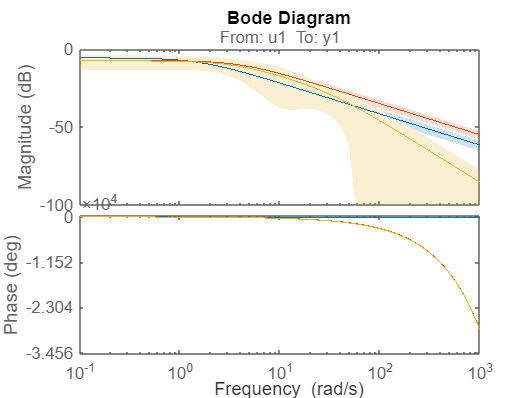

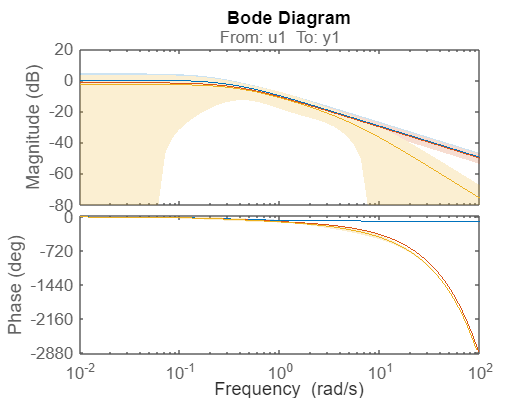

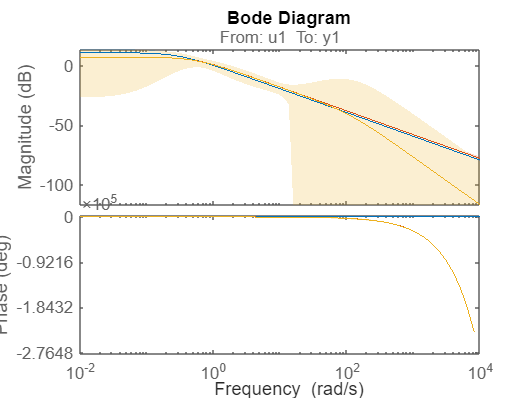

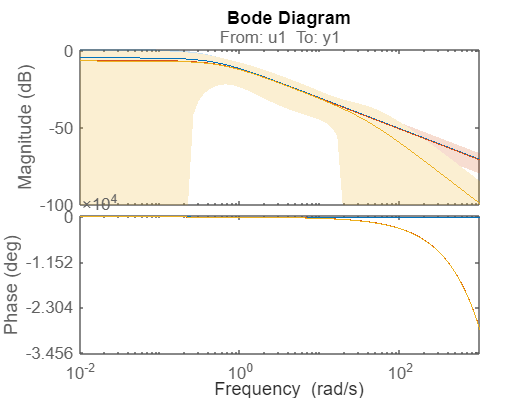

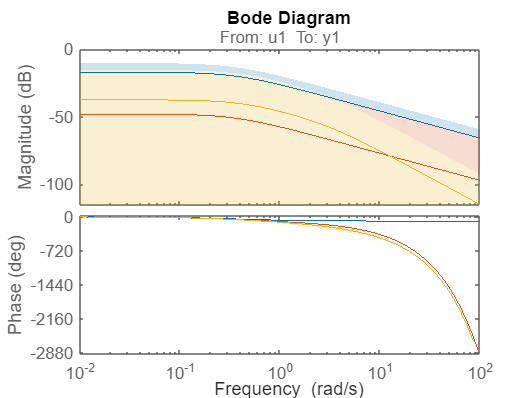

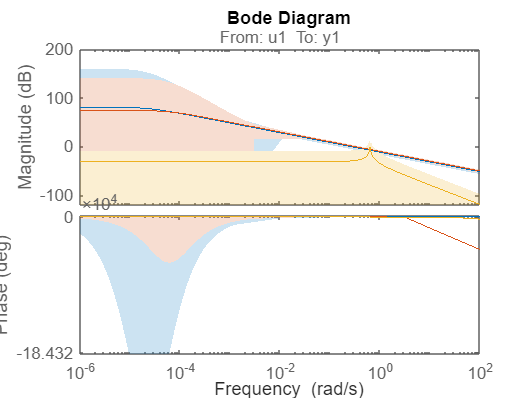

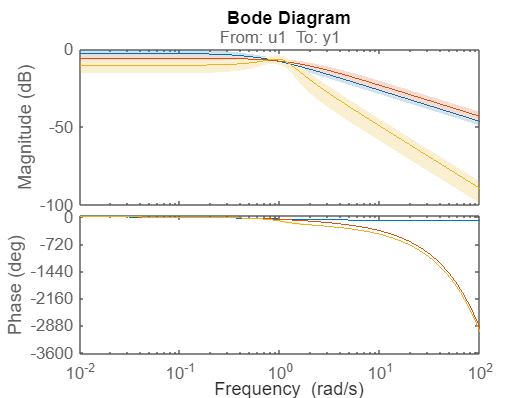

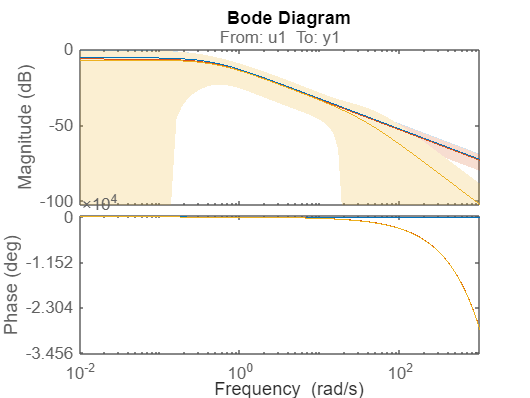

for i = 1:num_outputs
    figure, hold on,
    for j = 1:num_models
        h = bodeplot(G_ests{j, i});
        showConfidence(h,1)
    end
end